In this notebook, we intend to tune two hyperparameters of the error simulator based on another real test data.

clear; clc; close all;
warning('off');

% Define a DataLoader instance.
% Define the length of simulation and the corresponding sequence length.
lenSeries = 1000; % Sequence length.
simulationTime = 10; % The time that this sequence corresponds to.
dataLoader = DataLoader(lenSeries, simulationTime);
dataLoader.shuffle = false; % Shuffle the data.
dataLoader.readFromOriginalFiles = false;

% Parameters that defines motor accuracy.
dataLoader.errorBlockSize = 200; % The length of a error. The same error will persists for errorBlockSize points.

% Parameters related to the stuck failure.
dataLoader.stuckInstantIdx = 50;

% Range of the steady-state errors.
dataLoader.error_ll = 10;
dataLoader.error_ul = 20;


# Get the real data

dataLoader.pathLoggedTestData = '../dataset/testDatasets/20241008/real_testing_dataset.mat';
dataLoader.pathTestDataset = '../dataset/testDatasets/20241008/';
dataLoader.pathOriginalTestData = '../dataset/testDatasetsOriginal/20241008/';

dataLoader.labelList = {'Healthy'};

dataLoader.readFromOriginalFiles = false;
[X_test, y_test] = dataLoader.loadTestingData();

Loaded data from ../dataset/testDatasets/20241008/real_testing_dataset.mat


y_test = categorical(y_test);

dataLoader.visualization = false;

% Get the healty data.
label = dataLoader.labelList{1};
X_label = X_test(y_test==label);

% Intial values
n_sample = numel(X_label);
holdingTimes = [2, 5, 10, 15, 20]; % Search grid for holding time.
n_holdingTime = numel(holdingTimes);
n_sse = 3; % Number of error distribution

mse_res = zeros(n_sse, n_holdingTime);

i = 1;
fprintf('Loop for %d th error distribution:\n', i)

Loop for 1 th error distribution:


mean_residual = evalRes(n_holdingTime, n_sample, dataLoader, X_label, holdingTimes);

Current holding time: 2.00
1/10 iterations
residual error: 0.0605
2/10 iterations
residual error: 0.1266
3/10 iterations
residual error: 0.0632
4/10 iterations
residual error: 0.0205
5/10 iterations
residual error: 0.1328
6/10 iterations
residual error: 0.4305
7/10 iterations
residual error: 0.0878
8/10 iterations
residual error: 0.1713
9/10 iterations
residual error: 0.0348
10/10 iterations
residual error: 5.0782
Current holding time: 5.00
1/10 iterations
residual error: 0.0304
2/10 iterations
residual error: 0.0820
3/10 iterations
residual error: 0.0378
4/10 iterations
residual error: 0.0161
5/10 iterations
residual error: 0.0753
6/10 iterations
residual error: 0.3428
7/10 iterations
residual error: 0.0517
8/10 iterations
residual error: 0.1040
9/10 iterations
residual error: 0.0222
10/10 iterations
residual error: 4.9936
Current holding time: 10.00
1/10 iterations
residual error: 0.0140
2/10 iterations
residual error: 0.0331
3/10 iterations
residual error: 0.0229
4/10 iterations
res

clc;
mse_res(i, :) = mean_residual

mse_res =     0.6206    0.5756    0.5343    0.5406    0.5977
         0         0         0         0         0
         0         0         0         0         0



i = 2;
fprintf('Loop for %d th error distribution:\n', i)

Loop for 2 th error distribution:


dataLoader.errorValues = -3:3; % The possible errors on the positions, in robot control unit.
dataLoader.errorProb = [.1, .1, .1, .4, .1, .1, .1]; % Probability distribution of different errors.
mean_residual = evalRes(n_holdingTime, n_sample, dataLoader, X_label, holdingTimes);

Current holding time: 2.00
1/10 iterations
residual error: 0.0582
2/10 iterations
residual error: 0.1222
3/10 iterations
residual error: 0.0634
4/10 iterations
residual error: 0.0226
5/10 iterations
residual error: 0.1413
6/10 iterations
residual error: 0.4314
7/10 iterations
residual error: 0.0935
8/10 iterations
residual error: 0.1859
9/10 iterations
residual error: 0.0364
10/10 iterations
residual error: 5.0544
Current holding time: 5.00
1/10 iterations
residual error: 0.0402
2/10 iterations
residual error: 0.0895
3/10 iterations
residual error: 0.0424
4/10 iterations
residual error: 0.0206
5/10 iterations
residual error: 0.0647
6/10 iterations
residual error: 0.3543
7/10 iterations
residual error: 0.0572
8/10 iterations
residual error: 0.1087
9/10 iterations
residual error: 0.0409
10/10 iterations
residual error: 4.9960
Current holding time: 10.00
1/10 iterations
residual error: 0.0101
2/10 iterations
residual error: 0.0312
3/10 iterations
residual error: 0.0231
4/10 iterations
res

clc;
mse_res(i, :) = mean_residual

mse_res =     0.6206    0.5756    0.5343    0.5406    0.5977
    0.6209    0.5815    0.5300    0.5443    0.5889
         0         0         0         0         0



i = 3;
fprintf('Loop for %d th error distribution:\n', i)

Loop for 3 th error distribution:


dataLoader.errorValues = -5:5; % The possible errors on the positions, in robot control unit.
dataLoader.errorProb = [.07, .07, .07, .07, .07, .3, .07, .07, .07, .07, .07]; % Probability distribution of different errors.
mean_residual = evalRes(n_holdingTime, n_sample, dataLoader, X_label, holdingTimes);

Current holding time: 2.00
1/10 iterations
residual error: 0.0598
2/10 iterations
residual error: 0.1188
3/10 iterations
residual error: 0.0677
4/10 iterations
residual error: 0.0263
5/10 iterations
residual error: 0.1481
6/10 iterations
residual error: 0.4287
7/10 iterations
residual error: 0.1004
8/10 iterations
residual error: 0.2032
9/10 iterations
residual error: 0.0418
10/10 iterations
residual error: 5.0320
Current holding time: 5.00
1/10 iterations
residual error: 0.0545
2/10 iterations
residual error: 0.0981
3/10 iterations
residual error: 0.0515
4/10 iterations
residual error: 0.0248
5/10 iterations
residual error: 0.0613
6/10 iterations
residual error: 0.3729
7/10 iterations
residual error: 0.0619
8/10 iterations
residual error: 0.1159
9/10 iterations
residual error: 0.0633
10/10 iterations
residual error: 4.9643
Current holding time: 10.00
1/10 iterations
residual error: 0.0167
2/10 iterations
residual error: 0.0378
3/10 iterations
residual error: 0.0289
4/10 iterations
res

clc
mse_res(i, :) = mean_residual

mse_res =     0.6206    0.5756    0.5343    0.5406    0.5977
    0.6209    0.5815    0.5300    0.5443    0.5889
    0.6227    0.5868    0.5315    0.5494    0.5891


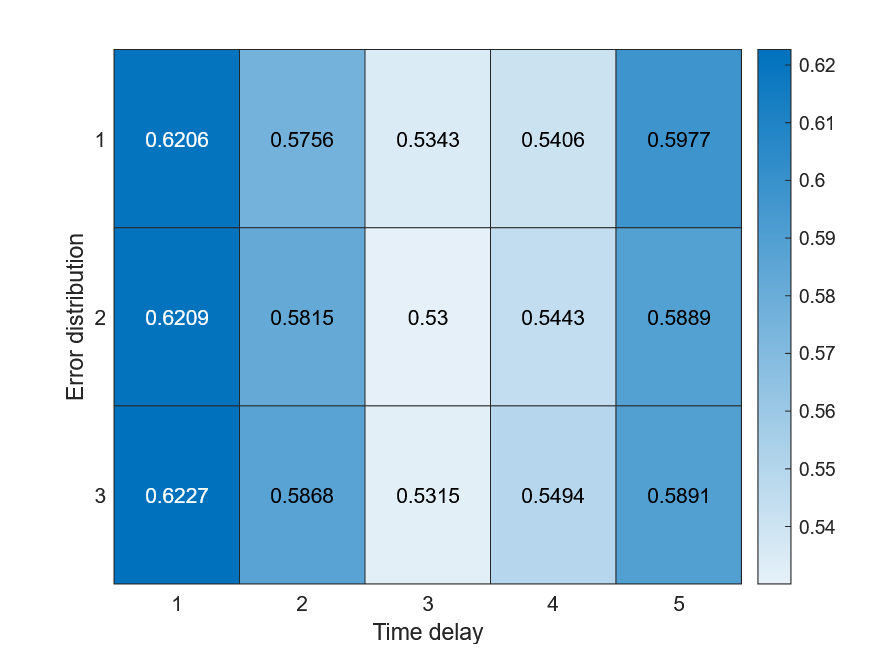


% Create heatmap
heatmap(mse_res);

% Optionally customize the heatmap
xlabel('Time delay');
ylabel('Error distribution');

function mean_residual = evalRes(n_holdingTime, n_sample, dataLoader, X_label, holdingTimes)
    % Set random seed for reproduction purpose.
    rng(10);
    residuals = zeros(n_sample, n_holdingTime);
    label = dataLoader.labelList{1};
    for k = 1:n_holdingTime
        fprintf('Current holding time: %.2f\n', holdingTimes(k));
        dataLoader.holdingTimeIdx = holdingTimes(k);
    
        for i = 1:n_sample
            fprintf('%d/%d iterations\n', i, n_sample);
        
            motorCmdsRadius = cell(1, 5);
            pathHiddenDataset = [dataLoader.pathTestDataset label '/' 'hidden_dataset_' num2str(i) '.mat'];
            hiddenDataset = load(pathHiddenDataset);
            motorRespsRadiusReal = hiddenDataset.motorRespsRadius;
            
            % Retrieve motor commands in radius.
            X_run = X_label{i};    
            for j = 1:5
                motorCmdsRadius{j} = timeseries(table2array(X_run(:, j+1)), table2array(X_run(:, 1)));
            end
        
            % Run simulation for the same cmd.
            motorCmds = dataLoader.cmdsRadius2Unit(motorCmdsRadius);
            failureType = 0;
            dataLoader.runSimulation(motorCmds, failureType);
            motorRespsRadiusSim = dataLoader.motorResponsesRadius;
        
            % Get the desired and realized traj.
            trajRespReal = dataLoader.virtualSensor(motorRespsRadiusReal);
            trajRespSim = dataLoader.virtualSensor(motorRespsRadiusSim);
            residualError = sum(sum((trajRespSim-trajRespReal).*(trajRespSim-trajRespReal)));
        
            fprintf('residual error: %.4f\n', residualError);
            residuals(i, k) = residualError;
        end
    end
    mean_residual = mean(residuals);
end
